Loading vibration_data.csv...


--------------------------------------------


Preview of Loaded Vibration Dataset:


       time         accel        label   
    __________    _________    __________

             0            0    {'normal'}
    8.3333e-05    0.0052354    {'normal'}
    0.00016667     0.010467    {'normal'}
       0.00025     0.015692    {'normal'}
    0.00033333     0.020906    {'normal'}
    0.00041667     0.026105    {'normal'}
        0.0005     0.031287    {'normal'}
    0.00058333     0.036447    {'normal'}
    0.00066667     0.041582    {'normal'}
       0.00075     0.046689    {'normal'}



--------------------------------------------


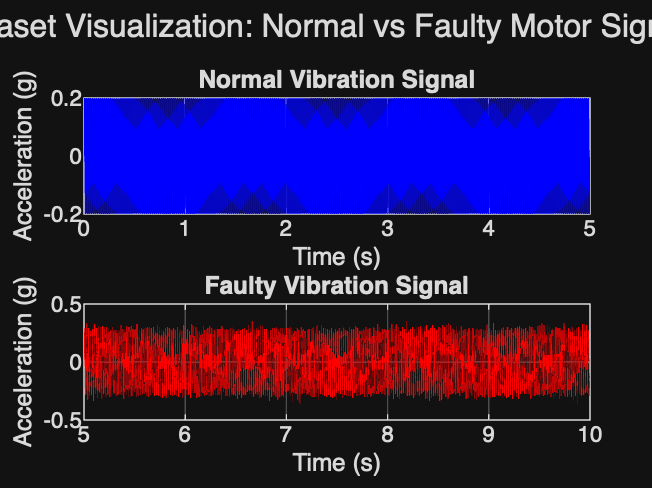

%% ================================================================
%  Predictive Maintenance using Vibration Analysis
%  ------------------------------------------------
%  Author : <Your Name>
%  Description : Detect motor faults using DSP + ML
%  ================================================================


clc; clear; close all;


%% -------------------- PARAMETERS --------------------
fs = 12000;                % Sampling frequency (Hz)
segmentLength = fs;        % 1-second segment length
lowcut = 10;
highcut = 5000;


%% -------------------- LOAD DATA --------------------
fileName = 'vibration_data.csv';


if isfile(fileName)
    disp('Loading vibration_data.csv...');
    data = readtable(fileName);
    time  = data.time;
    accel = data.accel;
    label = string(data.label); % Ensure label is string array


    % === Display dataset preview ===
    disp('--------------------------------------------');
    disp('Preview of Loaded Vibration Dataset:');
    disp(data(1:10,:));
    disp('--------------------------------------------');


    % === Plot Normal vs Faulty Signals ===
    figure;
    subplot(2,1,1);
    plot(time(label=="normal"), accel(label=="normal"), 'b');
    title('Normal Vibration Signal');
    xlabel('Time (s)');
    ylabel('Acceleration (g)');
    grid on;


    subplot(2,1,2);
    plot(time(label=="fault"), accel(label=="fault"), 'r');
    title('Faulty Vibration Signal');
    xlabel('Time (s)');
    ylabel('Acceleration (g)');
    grid on;


    sgtitle('Dataset Visualization: Normal vs Faulty Motor Signals');


else
    % ---- Synthetic demo signal (runs without file) ----
    disp('No file found -> generating synthetic vibration signal...');
    t = (0:1/fs:10-1/fs)'; % Create as column vector
    
    healthy = 0.2*sin(2*pi*50*t);
    faulty  = 0.2*sin(2*pi*50*t) + 0.05*sin(2*pi*300*t) + 0.03*randn(size(t));
    
    accel   = [healthy; faulty]; % Combine vertically
    time    = (0:length(accel)-1)'/fs; % Create as column vector
    
    % Create labels as column vector
    label_healthy = repmat("normal", length(healthy), 1);
    label_faulty  = repmat("fault", length(faulty), 1);
    label         = [label_healthy; label_faulty];


    % Convert to table for display
    data = table(time, accel, label, 'VariableNames', {'time','accel','label'});
    disp('--------------------------------------------');
    disp('Preview of Synthetic Dataset:');
    disp(data(1:10,:));
    disp('--------------------------------------------');


    % === Plot synthetic signals ===
    figure;
    subplot(2,1,1);
    plot(time(label=="normal"), accel(label=="normal"), 'b');
    title('Normal (Healthy) Vibration Signal');
    xlabel('Time (s)');
    ylabel('Acceleration (g)');
    grid on;


    subplot(2,1,2);
    % --- FIX: Plot correct portion of time and accel for faulty ---
    plot(time(label=="fault"), accel(label=="fault"), 'r');
    title('Faulty Vibration Signal');
    xlabel('Time (s)');
    ylabel('Acceleration (g)');
    grid on;


    sgtitle('Synthetic Dataset Visualization: Normal vs Faulty');
end

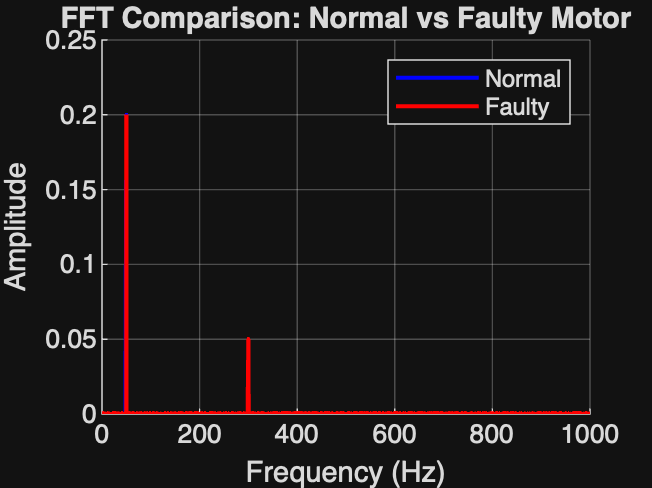



%% -------------------- FREQUENCY DOMAIN COMPARISON --------------------
figure;
hold on;
normal_accel = accel(label=="normal");
fault_accel  = accel(label=="fault");


% Ensure both signals have same length for proper comparison
minLen = min(length(normal_accel), length(fault_accel));
normal_accel = normal_accel(1:minLen);
fault_accel  = fault_accel(1:minLen);


N = length(normal_accel);


% --- FIX ---
% Check if N is zero (e.g., no "normal" data was found) to prevent errors
if N == 0 || minLen == 0
    disp('No "normal" or "fault" data found to compare in FFT. Skipping FFT plot.');
else
    % Plot single-sided spectrum
    % Calculate FFT for normal signal
    Fn = fft(normal_accel);
    Pn = abs(Fn/N);
    Pn_single = Pn(1:floor(N/2)+1);
    Pn_single(2:end-1) = 2*Pn_single(2:end-1);
    
    % Calculate FFT for faulty signal
    Ff = fft(fault_accel);
    Pf = abs(Ff/N);
    Pf_single = Pf(1:floor(N/2)+1);
    Pf_single(2:end-1) = 2*Pf_single(2:end-1);
    
    % Define frequency vector
    f_single = fs*(0:floor(N/2))/N;


    plot(f_single, Pn_single, 'b', 'LineWidth', 1.5); % 'b' = Blue
    plot(f_single, Pf_single, 'r', 'LineWidth', 1.5); % 'r' = Red
    xlim([0 1000]); % Focus on relevant frequency range
    title('FFT Comparison: Normal vs Faulty Motor');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    legend('Normal','Faulty');
    grid on;
end
hold off;

% --- END FIX ---


%% -------------------- FILTERING --------------------
% Apply a bandpass filter to remove noise and focus on relevant frequencies
disp('Applying bandpass filter...');

Applying bandpass filter...


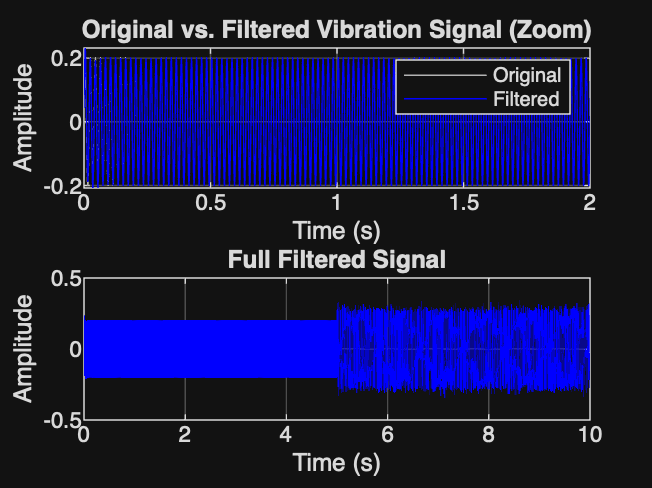

[b,a] = butter(4,[lowcut highcut]/(fs/2),'bandpass');
filtered = filtfilt(b,a,accel);


figure;
subplot(2,1,1);
plot(time, accel, 'color', [0.7 0.7 0.7]);
hold on;
plot(time, filtered, 'b');
title('Original vs. Filtered Vibration Signal (Zoom)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Filtered');
xlim([0 2]); % Zoom in to see the effect
grid on;


subplot(2,1,2);
plot(time, filtered, 'b');
title('Full Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;



%% -------------------- SEGMENT + FEATURE EXTRACTION --------------------
disp('Segmenting signal and extracting features...');

Segmenting signal and extracting features...


numSegments = floor(length(filtered)/segmentLength);
% Handle case where there are no full segments
if numSegments == 0
    error('Signal is too short to create any full segments. Check segmentLength or data.');
end


features = [];
targets = [];


for i = 1:numSegments
    % Define the start and end of the segment
    segStart = (i-1)*segmentLength + 1;
    segEnd   = i*segmentLength;
    segment  = filtered(segStart : segEnd);


    % --- Time domain features ---
    meanVal = mean(segment);
    rmsVal  = rms(segment);
    varVal  = var(segment);
    kurtVal = kurtosis(segment);
    
    % --- IMPROVEMENT: Added Crest Factor and Skewness ---
    peakVal = max(abs(segment));
    % Avoid division by zero if rms is 0 (e.g., segment of all zeros)
    if rmsVal == 0
        crestFactor = NaN; 
    else
        crestFactor = peakVal / rmsVal; % Excellent for detecting impacts
    end
    skewVal = skewness(segment);      % Measures signal asymmetry
    
    % --- Frequency domain features ---
    Y = fft(segment);
    L = length(segment);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    freq = fs*(0:(L/2))/L;
    
    [~,maxIdx] = max(P1);
    maxFreq = freq(maxIdx);        % Frequency with the most power
    spectralEnergy = sum(P1.^2); % Total energy in the spectrum


    % Add all features to the matrix
    features = [features; meanVal, rmsVal, varVal, kurtVal, crestFactor, skewVal, maxFreq, spectralEnergy];
    
    % Get the label for this segment (use the label from the start)
    targets = [targets; label(segStart)];
end


% --- IMPROVEMENT: Handle any NaN features (e.g., from crest factor) ---
% We replace NaN with 0, a simple form of imputation.
features(isnan(features)) = 0;


% --- IMPROVEMENT: Updated featureNames list ---
featureNames = {'Mean','RMS','Variance','Kurtosis','CrestFactor','Skewness','MaxFreq','SpectralEnergy'};


disp('Extracted feature matrix size:');

Extracted feature matrix size:


disp(size(features));

    10     8



disp('Feature Names:');

Feature Names:


disp(featureNames);

    {'Mean'}    {'RMS'}    {'Variance'}    {'Kurtosis'}    {'CrestFactor'}    {'Skewness'}    {'MaxFreq'}    {'SpectralEnergy'}





%% -------------------- MACHINE LEARNING (K-FOLD CROSS-VALIDATION) --------------------
disp('Training and testing machine learning model using 10-Fold Cross-Validation...');

Training and testing machine learning model using 10-Fold Cross-Validation...




% --- IMPROVEMENT: Using K-Fold Cross-Validation for a more robust accuracy assessment ---
K = 10;
cv = cvpartition(targets,'KFold',K);


accuracies = zeros(K,1);
allYTest = [];
allYPred = [];
mdl = []; % Initialize model variable


for k = 1:K
    fprintf('Processing K-Fold %d/%d...\n', k, K);
    
    % Get training and test indices for this fold
    idxTrain = training(cv, k);
    idxTest  = test(cv, k);
    
    XTrain = features(idxTrain,:);
    YTrain = targets(idxTrain);
    XTest  = features(idxTest,:);
    YTest  = targets(idxTest);
    
    % Train an ensemble of bagged decision trees
    mdl = fitcensemble(XTrain,YTrain,'Method','Bag');
    
    % Predict on the test set for this fold
    YPred = predict(mdl,XTest);
    
    % --- FIX: Convert YPred from categorical to string to match YTest ---
    YPred = string(YPred);
    % --- END FIX ---
    
    % Calculate and store accuracy for this fold
    confMat_k = confusionmat(YTest, YPred);
    accuracies(k) = sum(diag(confMat_k)) / sum(confMat_k(:));
    
    % Store all true labels and predictions to build one final confusion matrix
    allYTest = [allYTest; YTest];
    allYPred = [allYPred; YPred];
end

Processing K-Fold 1/10...
Processing K-Fold 2/10...
Processing K-Fold 3/10...
Processing K-Fold 4/10...
Processing K-Fold 5/10...
Processing K-Fold 6/10...
Processing K-Fold 7/10...
Processing K-Fold 8/10...
Processing K-Fold 9/10...
Processing K-Fold 10/10...




% --- Final Results ---
meanAccuracy = mean(accuracies) * 100;
stdAccuracy  = std(accuracies) * 100;


fprintf('\n--- Machine Learning Results (10-Fold Cross-Validation) ---\n');


--- Machine Learning Results (10-Fold Cross-Validation) ---


fprintf('Mean Accuracy: %.2f %% \n', meanAccuracy);

Mean Accuracy: 100.00 % 


fprintf('Standard Deviation of Accuracy: %.2f %% \n', stdAccuracy);

Standard Deviation of Accuracy: 0.00 % 




% --- IMPROVEMENT: Calculate Precision, Recall, and F1-Score ---
% We will calculate these metrics for the 'fault' class, as that's
% what we are most interested in detecting.


% Create a confusion matrix from all test folds
C = confusionmat(allYTest, allYPred);


% Get the class order
classOrder = categories(categorical(targets));
faultIdx = find(classOrder == "fault");
normalIdx = find(classOrder == "normal");


if isempty(faultIdx) || isempty(normalIdx)
    disp('Could not find both "normal" and "fault" classes in test results.');
    % Handle case with only one class
    if ~isempty(faultIdx) && size(C,1) >= faultIdx && size(C,2) >= faultIdx % Only fault
        TP = C(faultIdx, faultIdx);
        FP = 0; FN = 0;
    else % Only normal or error
        TP = 0; FP = 0; FN = 0;
    end
else
    % Re-assign standard TP, FP, FN based on class indices
    TP = C(faultIdx, faultIdx); % True Positives (Fault detected as Fault)
    FP = C(normalIdx, faultIdx);% False Positives (Normal detected as Fault)
    FN = C(faultIdx, normalIdx);% False Negatives (Fault detected as Normal)
end


% Avoid division by zero if a class is never predicted
if (TP + FP) == 0
    precision = 0;
else
    precision = TP / (TP + FP);
end


if (TP + FN) == 0
    recall = 0;
else
    recall = TP / (TP + FN);
end


if (precision + recall) == 0
    f1Score = 0;
else
    f1Score = 2 * (precision * recall) / (precision + recall);
end


fprintf('\nMetrics for "fault" class:\n');


Metrics for "fault" class:


fprintf('Precision: %.3f (Of all "fault" predictions, %.1f%% were correct)\n', precision, precision*100);

Precision: 1.000 (Of all "fault" predictions, 100.0% were correct)


fprintf('Recall:    %.3f (Of all actual "faults", we found %.1f%%)\n', recall, recall*100);

Recall:    1.000 (Of all actual "faults", we found 100.0%)


fprintf('F1-Score:  %.3f (Harmonic mean of Precision and Recall)\n', f1Score);

F1-Score:  1.000 (Harmonic mean of Precision and Recall)


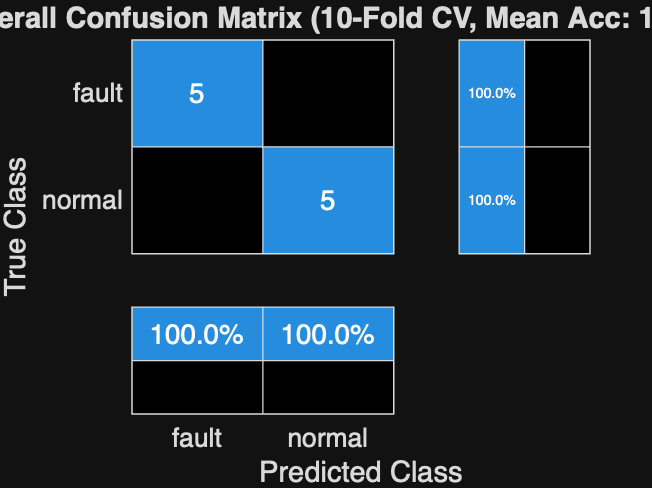



% Display the *overall* confusion matrix from all folds
figure;
cm = confusionchart(allYTest, allYPred);
cm.Title = sprintf('Overall Confusion Matrix (10-Fold CV, Mean Acc: %.2f%%)', meanAccuracy);
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

Calculating feature importance...


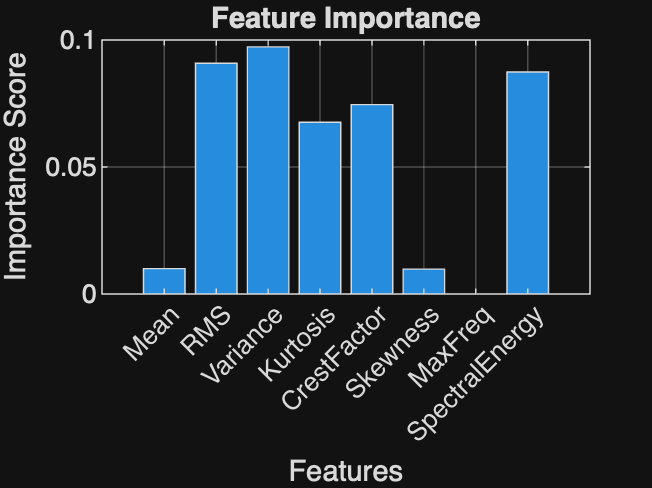



% --- NEW: FEATURE IMPORTANCE VISUALIZATION ---
% Requires a model to be trained. We'll use the one from the last K-Fold.
if ~isempty(mdl)
    disp('Calculating feature importance...');
    try
        % Get feature importance
        imp = predictorImportance(mdl);
        
        % Create a bar chart
        figure;
        bar(imp);
        title('Feature Importance');
        ylabel('Importance Score');
        xlabel('Features');
        % Set the feature names as labels on the x-axis
        xticklabels(featureNames);
        % Rotate labels for better readability
        xtickangle(45);
        grid on;
    catch ME
        fprintf('Could not compute or plot feature importance. Error: %s\n', ME.message);
    end
else
    disp('Cannot plot feature importance: Model was not trained.');
end



%% -------------------- POST-ANALYSIS VISUALIZATION --------------------
% Visualize the time and frequency domain of a single representative segment


disp('Visualizing a single sample segment...');

Visualizing a single sample segment...


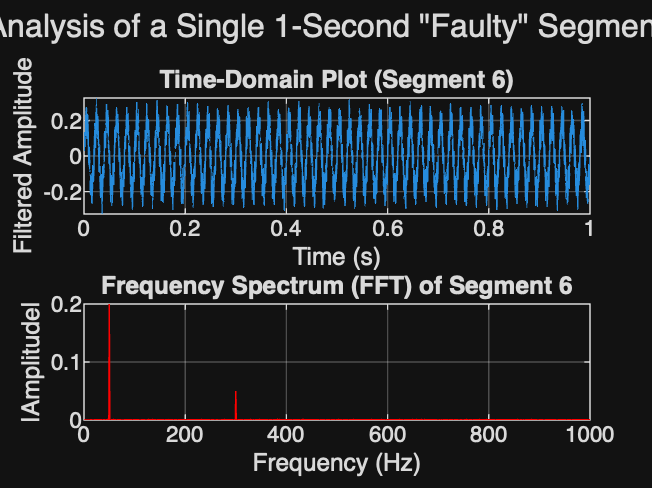



figure;
sgtitle('Analysis of a Single 1-Second "Faulty" Segment');


% Find the first "fault" segment to analyze
segmentIdx = find(targets == "fault", 1);
if isempty(segmentIdx)
    % Or just use the first segment if no fault is found
    segmentIdx = 1;
    sgtitle('Analysis of a Single 1-Second "Normal" Segment');
end


% Get the time and data for that segment
segStart = (segmentIdx-1)*segmentLength + 1;
segEnd   = segmentIdx*segmentLength;


% Ensure segment indices are valid
if segEnd > length(filtered) || segEnd > length(time)
    disp('Cannot plot single segment: Index out of bounds.');
else
    segment_data = filtered(segStart:segEnd);
    segment_time = time(segStart:segEnd);
    % Adjust time to start from 0 for this segment plot
    segment_time = segment_time - segment_time(1);
    
    % --- Plot 1: Time-Domain ---
    subplot(2,1,1);
    plot(segment_time, segment_data);
    title(sprintf('Time-Domain Plot (Segment %d)', segmentIdx));
    xlabel('Time (s)');
    ylabel('Filtered Amplitude');
    grid on;
    
    % --- Plot 2: Frequency-Domain (FFT of *this* segment) ---
    subplot(2,1,2);
    Y = fft(segment_data);
    L = length(segment_data); % L = segmentLength (12000)
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(L/2))/L;
    
    plot(f,P1, 'r'); % Plot in red to match fault color
    title(sprintf('Frequency Spectrum (FFT) of Segment %d', segmentIdx));
    xlabel('Frequency (Hz)');
    ylabel('|Amplitude|');
    grid on;
    xlim([0 1000]); % <-- This is the important fix!
end

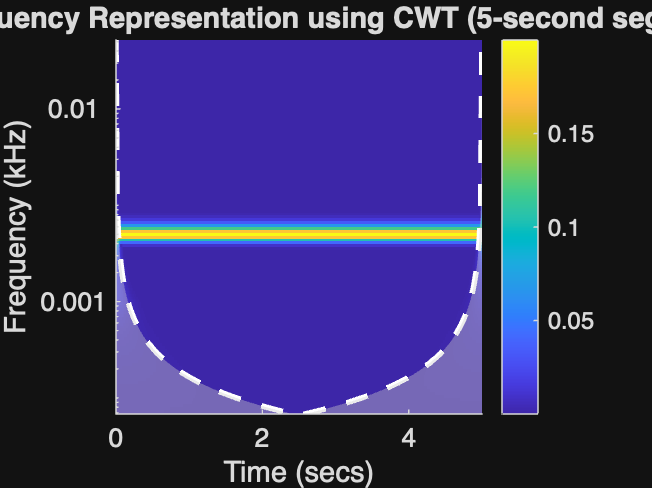



%% -------------------- WAVELET ANALYSIS --------------------
% Analyze a representative segment instead of entire signal
segmentForWavelet = filtered(1:min(5*fs, length(filtered))); % 5 seconds or less


if ~isempty(segmentForWavelet)
    figure;
    cwt(segmentForWavelet, fs);
    title('Time-Frequency Representation using CWT (5-second segment)');
    colorbar;
else
    disp('Signal too short for CWT analysis.');
end

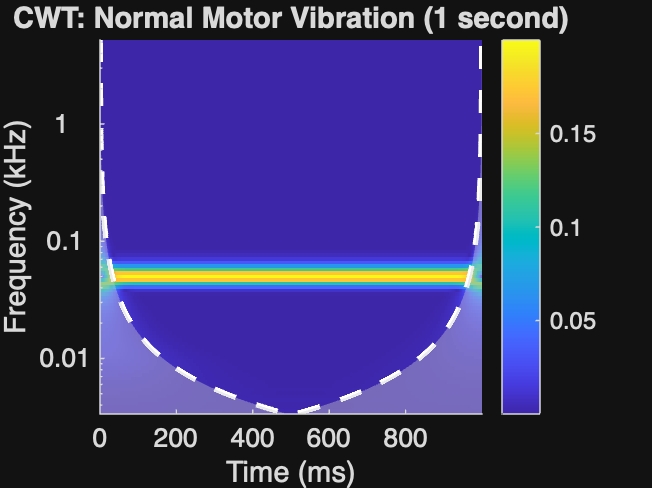



% Optional: Compare normal vs fault segments
figure;
subplot(2,1,1);
normalIdx = find(label=="normal", 1);
if ~isempty(normalIdx) && (normalIdx + fs - 1) <= length(filtered)
    normalSegment = filtered(normalIdx:normalIdx + fs - 1);
    cwt(normalSegment, fs);
    title('CWT: Normal Motor Vibration (1 second)');
    colorbar;
else
    disp('No 1-second "normal" segment found for CWT.');
end

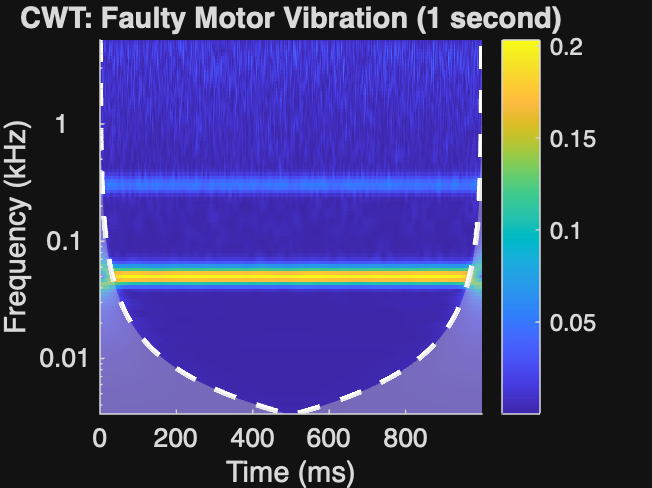



subplot(2,1,2);
faultIdx = find(label=="fault", 1);
if ~isempty(faultIdx) && (faultIdx + fs - 1) <= length(filtered)
    faultSegment = filtered(faultIdx:faultIdx + fs - 1);
    cwt(faultSegment, fs);
    title('CWT: Faulty Motor Vibration (1 second)');
    colorbar;
else
    disp('No 1-second "fault" segment found for CWT.');
end



%% -------------------- END --------------------
disp('--- Analysis Complete ---');

--- Analysis Complete ---
